# x-Dimensional MSI

## Background Introduction

- There were 7 whole-body animal (WBA) cryosections scanned by the air-flow-assisted desorption electrospray ionization mass spectrometry imaging method (AFADESI-MSI) under an ALTERNATIVELY switching mode.

- The alternative scan was composed of three channels: 

- Channel 1: m/z 50-1000 (positive); 

- Channel 2: m/z 50-1000 (negative); 

- Channel 3: t-SIM scan specific to drug ion: 

- PTX, 876.3203 [M+Na]+; PTR, 983.4172 [M+H]+; PTS, 1039.4440 [M+H]+

- Tumor cryosections were scanned by AFADESI-MSI SEPARATELY from the WBA sample for the purpose of gaining more detailed metabolic profile information.

- The 7 WBA samples were coded from A to G: (A) healthy control; (B) xenograft tumor (negative treatment); (C) paclitaxel (PTX); (D) paclitaxel derivative 1 (PTR); and (E) low, (F) medium, (G) high dosage of paclitaxel derivative 2 (PTS). 

- In this step-by-step procedure, the WBA data from Group A (healthy control) and Group B (negative treatment) were taken as the simplified demo data to illustratet the general workflow. The rest of group C-F data can be directly recalled from previously saved folders.

## Step prior to the formal pipeline

- Use the File Converter in the Xcalibur software to convert raws file into cdf format

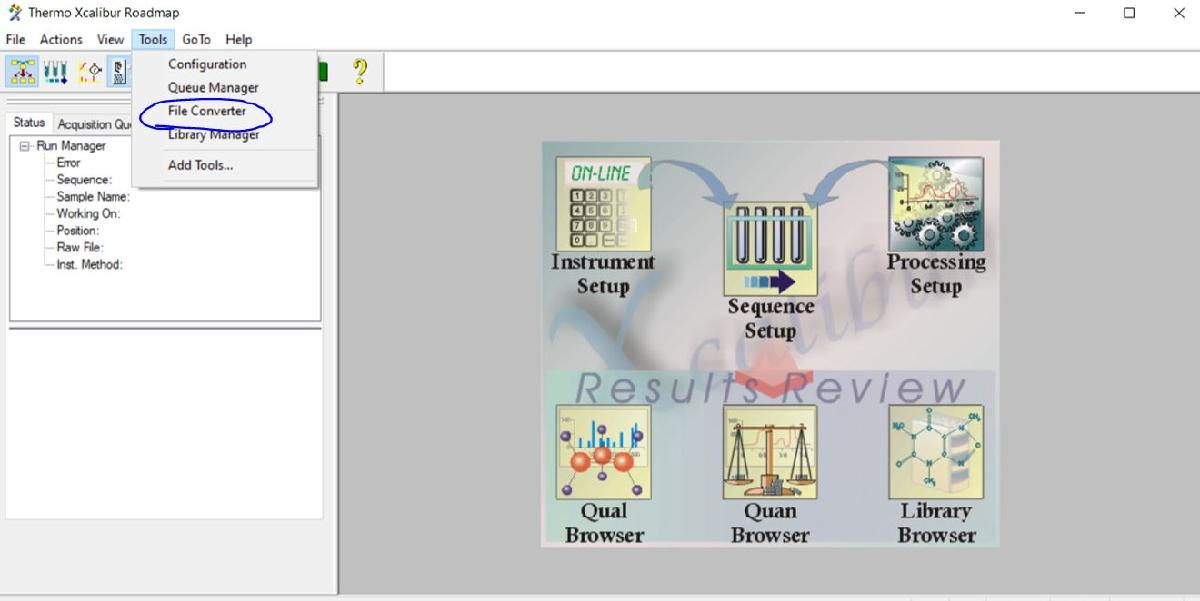

- specify the source data type, and folder, destination data type, and folder

- click "select all", "Add Job(s)", and "Convert".

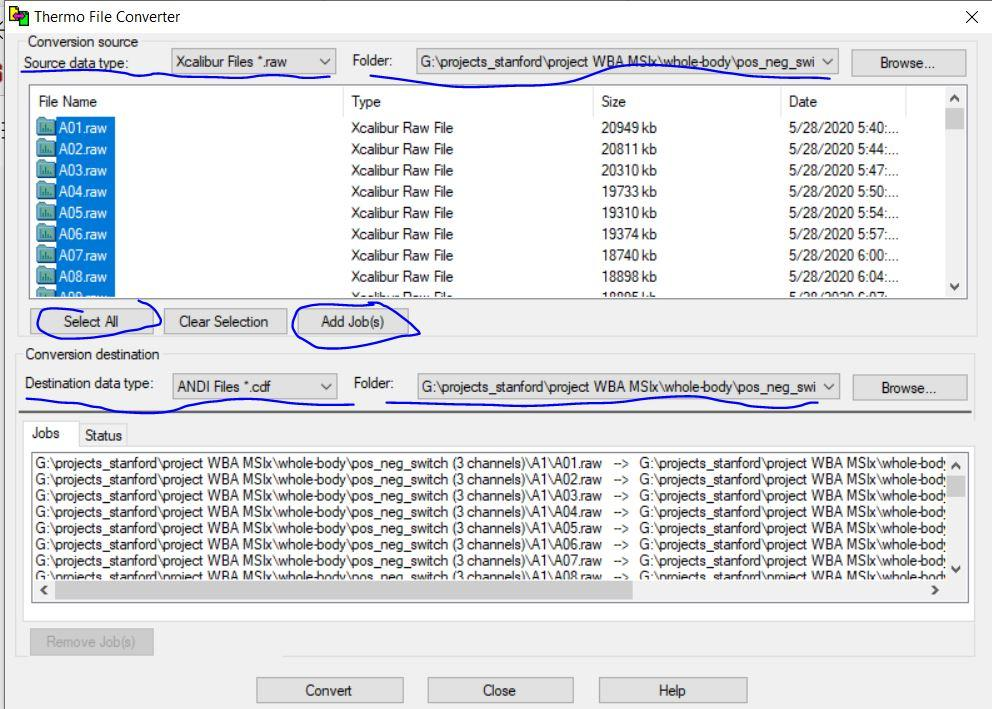

- check the converted cdf files in the specified destination folder

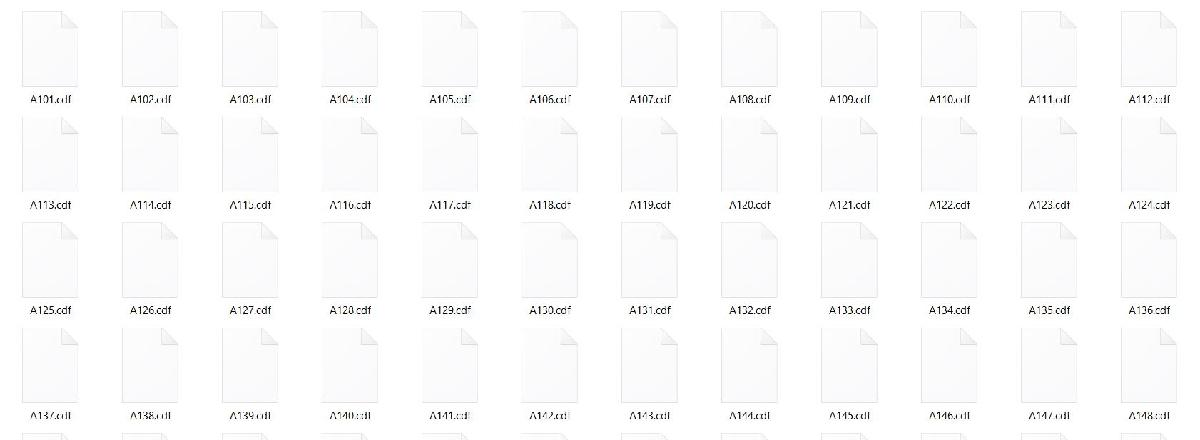

- paste converted CDF files into the current folder in the matlab platform

**General Pipeline**

Step 1：Import CDF Files and save as a peaklist

Step 2：Delineate the Region Of Interest and Register Pixel Index

Step 3：Generate the common peaks vector and construct a datacube

Step 4：Reduce the datacube volume size by SNR and PDR criteria

Step 5：Convert a datacube to a biomatrix

Step 6：Spatial Segmentation for WBA /tumor

Step 7：Biomatrix splitting and regional biomatrix recombination

Step 8：Regional Metabolomic Feature Extraction

Step 9：Measure the Metabolic Perturbation for global/high-order metabolomics

Step 10：Construct Metabolic Perturbation Image for WBA/tumor

## step 1. Import CDF Files and save as a peaklist

% reading series of No *.cdf files
% saved all of raw data into a cell named "peaklist"
% Take group A cdf files as an example
% suppose there are 70 cdf files
prefix='A1';
numOfFile=70
peaklist=batchcdfread(prefix,numOfFiles);
clear prefix numOfFiles
clc

- (Optional) Peaklist Splitting and Recombination

- If a peaklist is still too large to save in the folder, split the whole peaklist into several parts for storage separately.

subpeaklist1=peaklist(1:32,:);
subpeaklist2=peaklist(33:end,:);

- When needed, reload the subpeaklist into the workspace and combine them into one peaklist again

load('subpeaklistA1.mat')
load('subpeaklistA2.mat')
peaklist=[subpeaklist1;subpeaklist2];
clear subpeaklist1 subpeaklist2
clc

- Convert the profile MS data into centroid MS data

% Only preserve each peak's m/z and corresponding intensity values to save the storage
for i=1:length(peaklist)
    for j=1:length(peaklist{i})
        temp=peaklist{i,1}{j,1};
        peaklist{i,1}{j,1}=profile2centroid(temp);
    end
end
clear i j temp
clc

- Split the peaklist into three channel-specific peaklist

- Because an alternative scan were conducted on the whole-body animal section, the whole peaklist should be splitted into three parts and saved in a separate way.

for i=1:length(peaklist)
   peaklistneg{i,1}=peaklist{i,1}(1:3:end,1);
   peaklistpos{i,1}=peaklist{i,1}(2:3:end,1);
   peaklistdrug{i,1}=peaklist{i,1}(3:3:end,1);   
end
clear i
clc

## Step 2.Delineate the Region Of Interest and Register Pixel Index

- To remove the redundant pixels from the blank region

- Method 1: Automatic Selection according to sum of landmark ion intensities at each pixel and setted threshold value.

roimark_neg=[117.0193;118.0504;124.0064;132.0302;140.0117;...
    145.0619;151.0261;167.0207;171.0063;175.0240;191.0196;281.2468;...
    303.2317;371.1563;465.3057;515.2882;605.3062;663.3416;788.5441;885.5495];
% extract the negative landmark peak intensities of all pixels in the biomat
tolerance=0.005;
datacube_lm=batchmassimage(peaklistneg,roimark_neg,tolerance);
roimarksum=zeros(size(datacube_lm{1,2}))
for i=1:length(datacube_lm)
    roimarksum=roimarksum + datacube_lm{i,2};    
end
clear i tolerance roimark_neg
clc

% investigate and set up the pixel selection threshold
threshold=3E5;
roi=zeros(size(roimarksum,1)*size(roimarksum,2),1);
roi(roimarksum>threshold)=1;
roi=reshape(roi,[size(roimarksum,1),size(roimarksum,2)]);
imagesc(roi)

% generate the roi pixels' index
[bio_r,bio_c]=find(roi==1);
biopix_indx=[bio_r,bio_c];
clear bio_r bio_c threshold landmarksum
clc

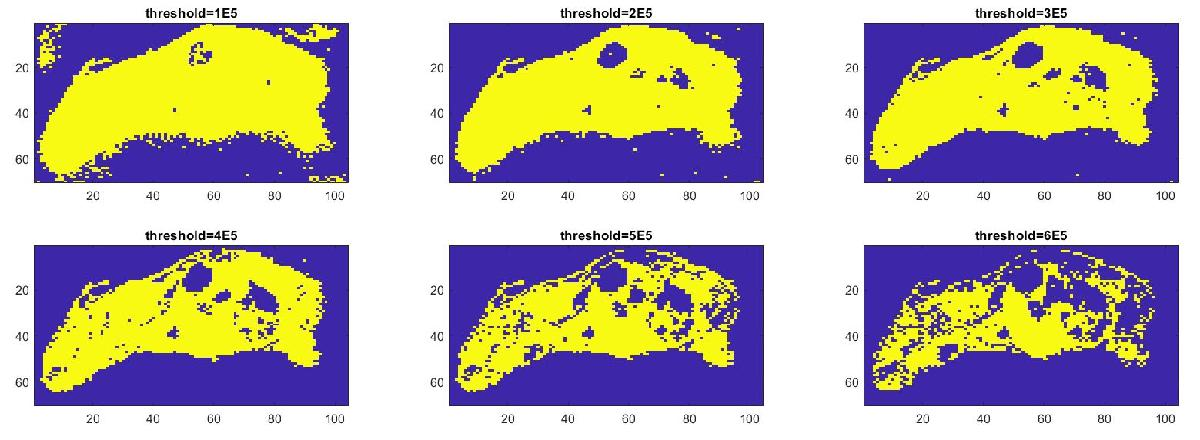

Figure. Automatic ROI region delineation. After trying different threshold value, you may find the optimal one to preserve the most of pixels across the biological section. In this study case, the optimal threshold should be around 3E5 for the sum of negative landmark peaks

- Method 2 (Optional, complementary with the automatic selection): Manual Selection. It is a quick way to get the ROI but weak in reproducibility and may also contain a few boundary background pixels. 

- When the automatic selection still contain some obvious background pixels, the manual selection becomes the complementary choice.

% arachidonic acid (m/z 303.2323) can be selected as the negative image template
imagesc(massimage(peaklist,104.1070,0.005));

Illegal use of reserved keyword "end".


% Optional: choline (m/z104.1070) can be selected as the positive image template
imagesc(massimage(peaklist,303,2323,0.005));
% manually draw the roi in the pop-up figure and then right click---create mask
roi=roipoly;

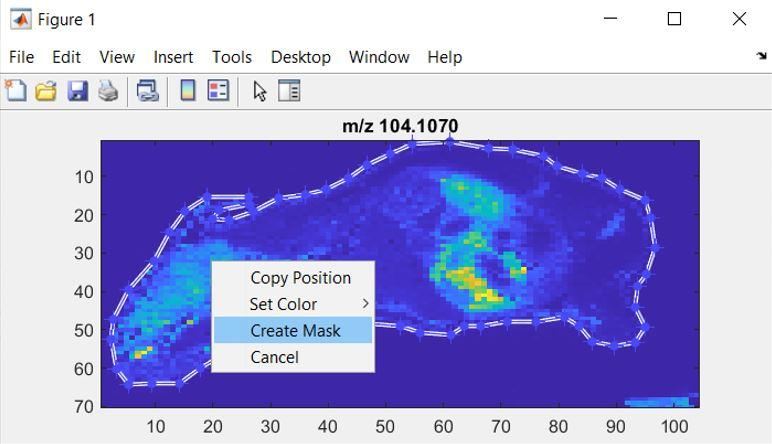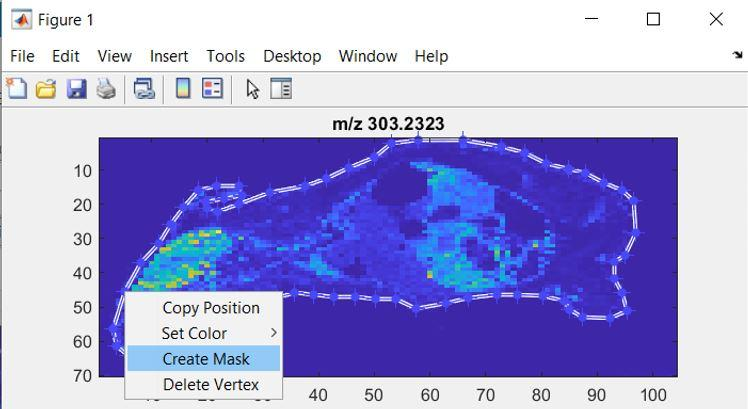

Figure. ROI region delineation by hand. The positive and negative image can share the same roi because of alternative scan data acquisition mode.

% Note: load the prestored demo data to reproduce the previous result 
load("roi_A.mat")

% generate the roi pixels' index
[bio_r,bio_c]=find(roi==1);
biopix_indx=[bio_r,bio_c];
clear bio_r bio_c threshold landmarksum
clc

## Step 3.Generate the common peaks vector and construct a datacube

- For untargeted metabolomics, the common peaks' m/z (cmz) values were binned from each MS scan given certain mass tolerance.

For generating the negative cmz

% note: it may take around 7-8 seconds in this section
cache=[];
tolerance=0.005;
for i=1:length(biopix_indx)
    cache=[cache;peaklistneg{biopix_indx(i,1),1}{biopix_indx(i,2)}(:,1)];
end

cache=sort(cache);
delta=[0;diff(cache)];
indx=find(delta>tolerance);
for i=1:length(indx)+1
    if i==1
       cmz_neg(i,1)=mean(cache(1:indx(1)-1));
    elseif i==length(indx)+1
       cmz_neg(i,1)=mean(cache(indx(i-1):end));
    else
       cmz_neg(i,1)=mean(cache(indx(i-1):indx(i)-1));
    end
end
clear indx i cache delta 
clc

for generating the positive cmz

% note: it may takes around 8-10 seconds in this section
cache=[];
for i=1:length(biopix_indx)
    cache=[cache;peaklistpos{biopix_indx(i,1),1}{biopix_indx(i,2)}(:,1)];
end

cache=sort(cache);
delta=[0;diff(cache)];
indx=find(delta>tolerance);
for i=1:length(indx)+1
    if i==1
       cmz_pos(i,1)=mean(cache(1:indx(1)-1));
    elseif i==length(indx)+1
       cmz_pos(i,1)=mean(cache(indx(i-1):end));
    else
       cmz_pos(i,1)=mean(cache(indx(i-1):indx(i)-1));
    end
end
clear indx i cache delta tolerance
clc

Construct the untarget datacube under both polarities.

SPECIAL NOTE: The following procedure takes a very long time (up to 25 mins) to complete when applied to the untarget metabolomics datacube construction

% mass tolerance was set at 0.005 for binning peaks
tolerance=0.005;
% construct the negative datacube (Channel1 negative Full MS)
% ***SPECIAL NOTE*** 
% it may take around 10-20 MINUTES to complete the run here
datacube_neg=batchmassimage(peaklistneg,cmz_neg,tolerance);
% construct the positive datacube (Channel 2 positive Full MS)
% ***SPECIAL NOTE*** 
% it may take around 20-24 MINUTES to complete the run here
datacube_pos=batchmassimage(peaklistpos,cmz_pos,tolerance);

- The above step may consume 10-25 minutes to complete. 

- To skip this step, one can directly load the stored demo data to continue the following steps.

load("cmz_neg.mat")
load("cmz_pos.mat")
% mass tolerance was set at 0.005 for binning peaks
tolerance=0.005;
% construct the negative datacube (Channel1 negative Full MS)
% NOTE: it may take around 20 seconds to complete the run here
datacube_neg=batchmassimage(peaklistneg,cmz_neg,tolerance);
% construct the positive datacube (Channel 2 positive Full MS)
% NOTE: it may take around 36 seconds to complete the run here
datacube_pos=batchmassimage(peaklistpos,cmz_pos,tolerance);

## Step 4. Reduce the datacube volume size by SNR and PDR criteria 

- NOTE: only applied to untarget metabolomics. 

- You can skip this section when conduct the target metabolomics program.

- Reduce the matrix volume by excluding noise and background peaks.

- Positive detection rate (PDR) and signal-to-noise ratio (SNR) are used for peak selection.

- PDR depicts the percentage of pixels that contain certain peak.

- SNR depicts the average intensity ratio of certain peak across the sample region(roi==1) and background region (roi==0).

% for the negative datacube
% get the pdr and snr values of each peak in the datacube
for i=1:length(datacube_neg)
    cache=datacube_neg{i,2}(:);
    int_roi=mean(cache(roi(:)==1));
    int_bk=mean(cache(roi(:)==0));
    pkdr_indx(i,1)=nnz(cache(roi(:)==1))/nnz(roi(:));
    pksnr_indx(i,1)=int_roi/int_bk;
end
clear i cache int_roi int_bk snr
clc
% set the snr threshold at 1.5 and pdr threshold at 0.01 (1%)
thres_snr=1.5;
thres_dr=0.01;
% only preserve those peaks with the SNR and PDR higher than the setted threshold values
% the ion which has SNR less than 1.5 will be regarded as BK ions and removed.
for i=1:length(cmz_neg)
  if pkdr_indx(i)>=thres_dr & pksnr_indx(i)>=thres_snr
     biopk_indx(i,1)=1;
  else
     biopk_indx(i,1)=0;
  end
end
clear i
clc
% extract the bioinformative peak images to form the biocube
biocube_neg=datacube_neg(biopk_indx==1,:);
biopk_neg=cell2mat(biocube_neg(:,1));
clear biopk_indx_neg biopk_indx_neg
clc

% for the positive datacube
% get the pdr and snr values of each peak in the datacube
% it may take around 12 seconds for completing the run here
for i=1:length(datacube_pos)
    cache=datacube_pos{i,2}(:);
    int_roi=mean(cache(roi(:)==1));
    int_bk=mean(cache(roi(:)==0));
    pkdr_indx(i,1)=nnz(cache(roi(:)==1))/nnz(roi(:));
    pksnr_indx(i,1)=int_roi/int_bk;
end
clear i cache int_roi int_bk snr
clc

% only preserve those peaks with the SNR and PDR higher than the setted threshold values
% the ion which has SNR less than 1.5 will be regarded as BK ions and removed.
for i=1:length(cmz_pos)
  if pkdr_indx(i)>=thres_dr & pksnr_indx(i)>=thres_snr
     biopk_indx(i,1)=1;
  else
     biopk_indx(i,1)=0;
  end
end
clear i
% extract the bioinformative peak images to form the biocube
biocube_pos=datacube_pos(biopk_indx==1,:);
biopk_pos=cell2mat(biocube_pos(:,1));
clear biopk_indx_pos biopk_indx_pos
clc

## Step 5.Convert a datacube to a biomatrix

- A biomatrix is composed of n rows -by- m columns.

- Each row represent a pixel and each column represents a peak (mass bin)

% Convert a datacube into biomatrix
for i=1:length(biocube_pos)
    temp=biocube_pos{i,2}(:);
    biomat_pos(:,i)=temp(find(roi==1));
end

for i=1:length(biocube_neg)
    temp=biocube_neg{i,2}(:);
    biomat_neg(:,i)=temp(find(roi==1));
end
clear i
clc
% manually check if any column from the biomatrix can be reconstructed into an authentic image 
% for example: pos. m/z 104.1010, Choline, [M+H]+
% example 2: neg. m/z 303.2323 arachidonic acid，[M-H]-
imagesc(indximg(biomat_pos(:,25),biopix_indx(:,1),biopix_indx(:,2)));
figure(2)
imagesc(indximg(biomat_neg(:,519),biopix_indx(:,1),biopix_indx(:,2)));

## Step 6.Spatial Segmentation for WBA/tumor

% data preprocessing
% TIC normalization
tic=sum(biomat_neg,2);
biomat_norm=1E7*biomat_neg./repmat(tic,1,size(biomat_neg,2));
% natural log transform
matnormlog=log(biomat_norm+1);
% use t-stochastic neighbouring embedding to compress the high-dimension
% data into a 3D feature space
lv=tsne(matnormlog,...
'algorithm','exact',...
'distance','euclidean',...
'NumPCAComponents',30,...
'Standardize',1,...
'perplexity',30,...
'exaggeration',10,...
'verbose',1,...
'NumDimensions',3);
% use k means clustering to give a raw segmentation result
label_rough=kmeans(lv(:,1:3),15);
figure(1)
scatter3(lv(:,1),lv(:,2),lv(:,3),10,label_rough);
% verification by remapping into the 2D space
figure(2)
imagesc(indximg(label_rough,biopix_indx(:,1),biopix_indx(:,2)));
colormap(jet(13));

- Note: At the stage of spatial segmentation model development, biological pixels are roughly classified (saved as "label_rough") by an unsupervised clustering method. Afterward, labelled pixels are carefully double-checked (saved as "label_precise") to removed those apparently wrong or ambiguous ones under guidance of optical image. Only those pixels with confident assignment are included into the final training dataset, which is composed of labled pixels from whole-body animal sections' image in the healthy control group. 

- % extract the regional biomatrix and save the intensity matrix and corresponding index matrix into the bioarray and indxarray, respectively.

- % Column Sequence for WBA group:  A: normal contrast (NC); B: xenograft model contrast (MC); C: paclitaxol (PTX); D: paclitaxel derivative 1 (PTR); E: paclitaxel derivative 2 low dosage (PTS (L)); F: paclitaxel derivative 2 medium dosage (PTS (M)); G: paclitaxel derivative 2 medium dosage (PTS (H));

- % Column Sequence for tumor: C (cancer); T(taxol); R(PTR); L(PTS(L)); M(PTS(M)); H(PTS(H))

- Row label for organs or tissues: 1. Heart  2. Lung  3. Spleen  4. kidney  5. brain  6. liver  7. Gastric  8. gastrointestinal (GI) tract 9. muscle  10. thymus 11. skin  12. gland  13. Jaw 14. gastrointestinal tract (GIT) contents; 15. Bone

- Row Label for tumor microcompartment: 1. stroma; 2. parenchyma; 3. Necrosis

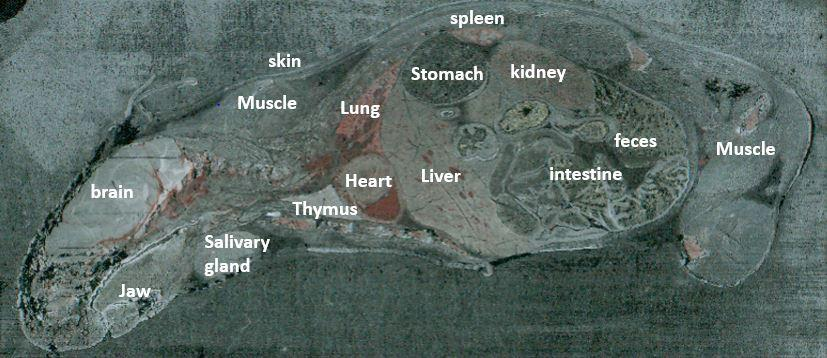 

- Figure. Optical image of the whole body animal (No.A from healthy control group)

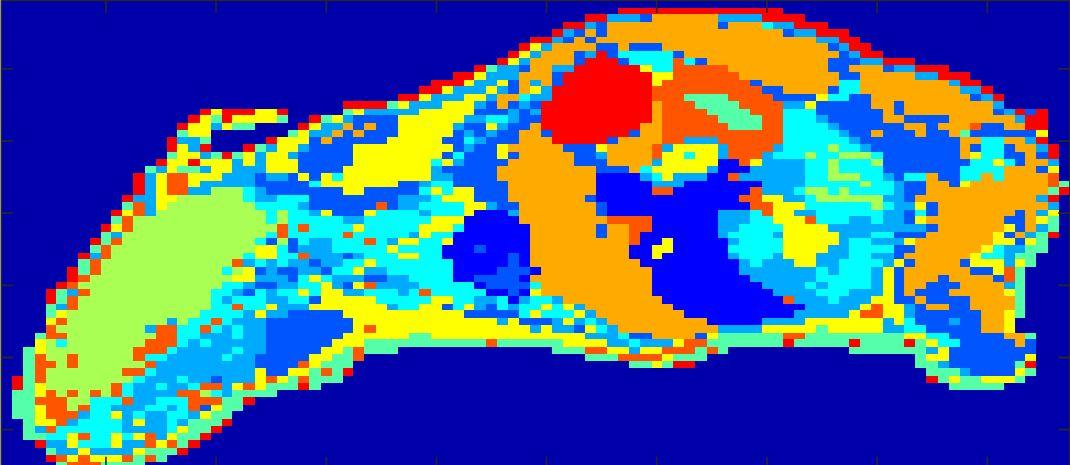

- Figure. spatial segmentation of the whole body animal by using tSNE-Kmeans clustering (No.A from healthy control group)

% recall the pretrained model to predict pixel label from another
% unseen WBA section image data, for example: matlog_B (WBA from the B group)
% the pretrained model is saved as "trainedModel_cosKNN.mat"
load('model_cosKNN.mat')
label_precise=cosKNN.predictFcn(biomat_norm);
% check the spatial segmentation performance by reconstructing the label
% image
label_image=indximg(label_precise,biopix_indx(:,1),biopix_indx(:,2));
imagesc(label_image);

- (Optional) Machine Learning Model Development for Spatial Segmentation

- You can either develop a machine learning model for spatial segmentation or directly use the pre-trained model by authors.

- The in-built app "classification learner" is an user-friendly way to train a model. The whole process can be completed in a graphic user interface (GUI). More details about this instruction can be accessed from the MATLAB help document.

% suppose we already have confidently labelled pixels save in the variabe
% named label_precise
trainset_target=label_precise;
trainset_input=matnorm;

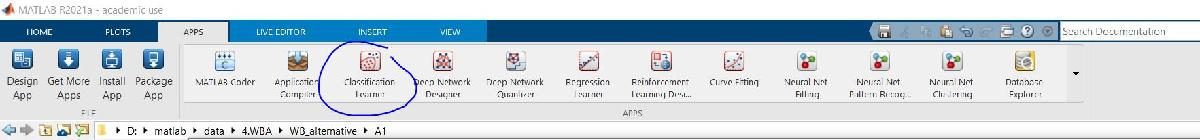

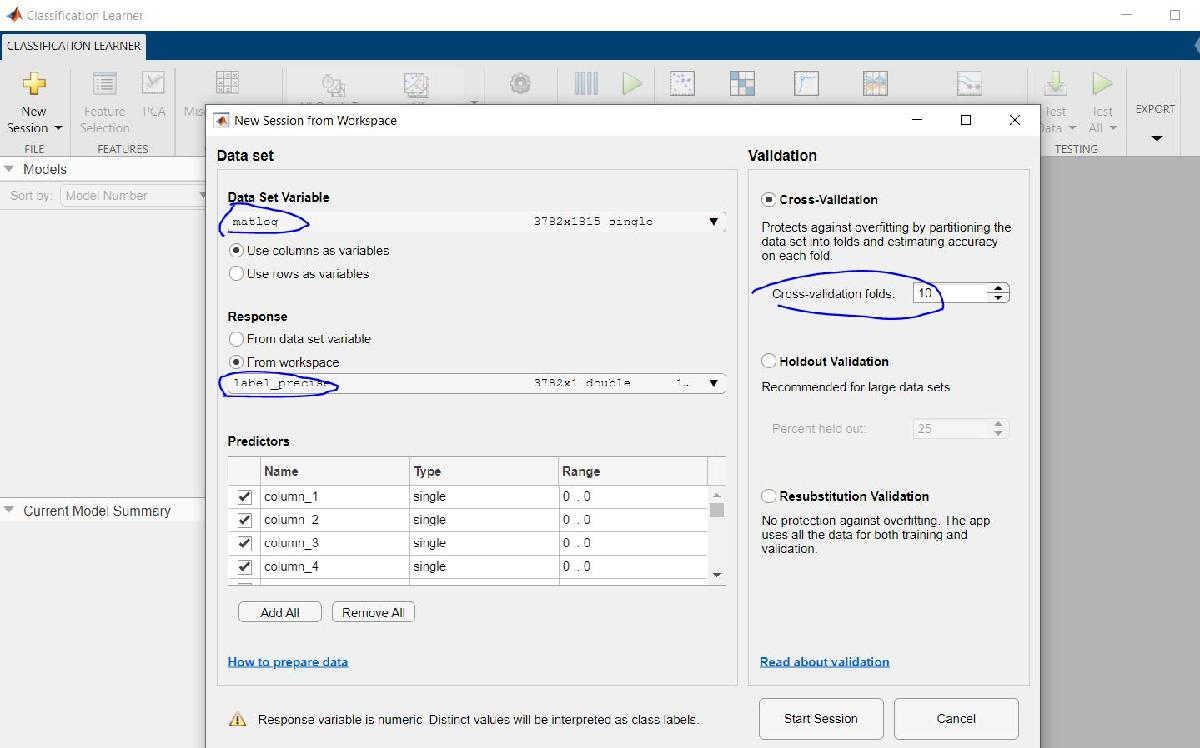

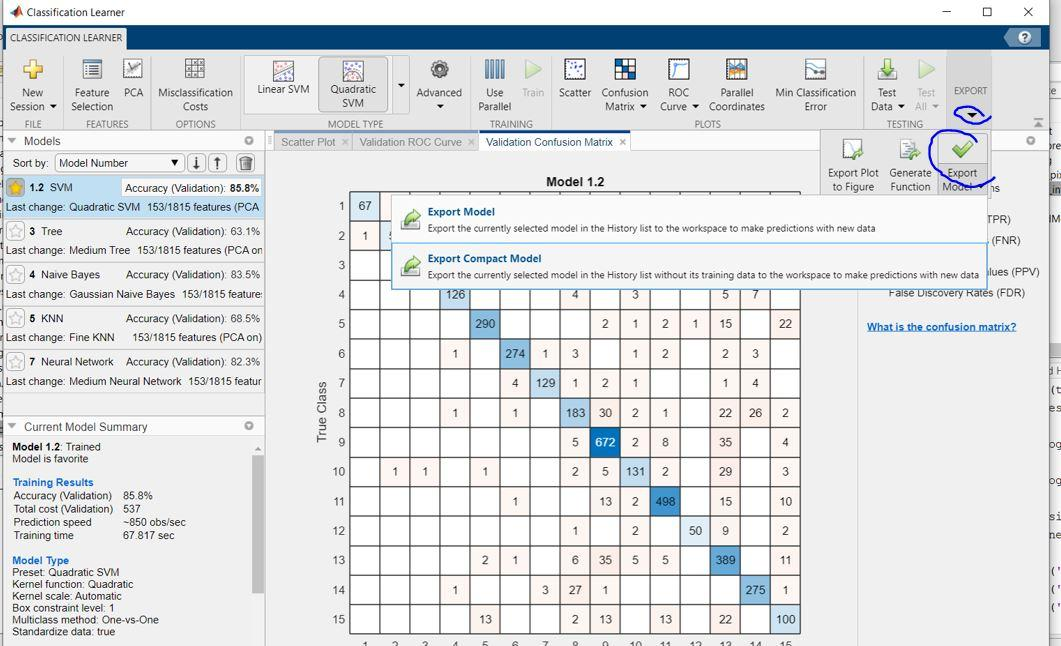

% to predict regional labels of unseen new data using the pre-developed model
label_precise=cosKNN.predictFcn(testset_neg);
% load the prestored label for reproduce the result 
load("label_precise_A.mat")

## Step 7. Biomatrix splitting and regional biomatrix recombination

% Create Group-based Structures
% extract the region-specific pixels and corresponding sub-biomatrix
% for group A data (as control), create a structure "structureA" including all necessary data for the
% following analysis
% combine the positive and the negative cmz into one cmz vector
biopk=[biopk_pos;biopk_neg];
numOfLabel=15;
% combine the positive and the negative biomat into one matrix
biomat=[biomat_pos,biomat_neg];

% construc a structure datatype variable
% NOTE: replace "X" in the "structureX" below with A, B, C, D, E, F, and G, respectively.
for i=1:numOfLabel
   structureX.regionBiomatArray{i,1}=biomat(label_precise==i,:);
   structureX.regionPixIndxArray{i,1}=biopix_indx(label_precise==i,:);
   structureX.regionPixNumber{i,1}=length(find(label_precise==i));
end
clear i numOfLabel
clc
structureX.regionLabel={'Heart';'Lung';'Spleen';'kidney';'brain';...
    'liver';'Gastric';'GI tract';'muscle';'thymus';'skin';...
    'gland';'Jaw';'GIT contents';'Bone'};
structureX.biopk=[biopk_pos;biopk_neg];
structureX.comment={"biopk_pos+biopk_neg"};
% Likewise, create structured variable for group B, C,D,E,F,G data including all necessary information for the
% following analysis

- re-combine a set of sub-biomat from different groups into a regional biomat

for i=1:numOfLabel
  packer{i,1}=[structureA.regionBiomatArray{i,1};...
     structureB.regionBiomatArray{i,1};...
     structureC.regionBiomatArray{i,1};...
     structureD.regionBiomatArray{i,1};...
     structureE.regionBiomatArray{i,1};...
     structureF.regionBiomatArray{i,1};...
     structureG.regionBiomatArray{i,1}];
  packer{i,2}=[repmat(1,length(structureA.regionPixIndxArray{i,1}),1);...
     repmat(2,length(structureB.regionPixIndxArray{i,1}),1);...
     repmat(3,length(structureC.regionPixIndxArray{i,1}),1);...
     repmat(4,length(structureD.regionPixIndxArray{i,1}),1);...
     repmat(5,length(structureE.regionPixIndxArray{i,1}),1);...
     repmat(6,length(structureF.regionPixIndxArray{i,1}),1);...
     repmat(7,length(structureG.regionPixIndxArray{i,1}),1)];
  packer{i,3}=[structureA.regionPixIndxArray{i,1};...
     structureB.regionPixIndxArray{i,1};...
     structureC.regionPixIndxArray{i,1};...
     structureD.regionPixIndxArray{i,1};...
     structureE.regionPixIndxArray{i,1};...
     structureF.regionPixIndxArray{i,1};...
     structureG.regionPixIndxArray{i,1}];
end
clear i structureA structureB structureC structureD structureE structureF structureG
clc

## Step 8. Regional Metabolomic Feature Extraction

% extract the spatial metabolomic feature from each region using t-SNE
% NOTE: this step may take around 10-15 MINUTES
for i=1:numOfLabel
  cache=packer{i,1};
  % TIC norm
  tic=sum(cache,2);
  cacheNorm=1E7*cache./repmat(tic,1,size(cache,2));
  cacheNormLog=log(cacheNorm+1);
  % Feature Extraction by t-SNE
  featureArray{i,1}=tsne(cacheNormLog,'algorithm','exact','distance','euclidean',...
    'NumPCAComponents',100,'Standardize',1,'perplexity',30,'exaggeration',7,...
    'verbose',1,'NumDimensions',2);
end
clear i tic cache cacheNorm cacheNormLog
clc

## Step 9. Measure the Metabolic Perturbation for global/high-order metabolomics

% Distance measurement using Mahalanobis method
% the group A (No 1, healthy control) was taken as the refence group
% recall the restored demo data to reproduce the results
load("featureArray_untarget_wba.mat")

% set the reference group number
RefIndex=1;
% compute the distance between each pixel and the centroid of reference
% group pixels
for i=1:length(featureArray)
  feature=featureArray{i,1};
  feature_ref=feature(packer{i,2}==RefIndex,:);
  distanceArray{i,1}=sqrt(mahal(feature,feature_ref));
  feature_ref=[];
  feature=[];
end
clear i feature feature_ref
clc

% extract and recombine every regional perturbation score vector derived from the same group 
numOfGroup=7;
numOfLabel=15;
for i=1:numOfGroup
    perturbScore=[];
    pxindx=[];
  for j=1:numOfLabel
     k=1:length(distanceArray{j,1});
     pxindx_cache=packer{j,3}(packer{j,2}(1:k)==i,:);
     score_cache=distanceArray{j,1}(packer{j,2}(1:k)==i);
     perturbScore=[perturbScore;score_cache];
     pxindx=[pxindx;pxindx_cache];
     pxindx_cache=[];
     score_cache=[];
  end
    wbScoreArray{i,1}=perturbScore;
    wbIndxArray{i,1}=pxindx;
end
clear i j pxindx_cache score_cache pertubScore
clc

% calculate the average perturbation score of each region in whole-body
regionScore(1,2:8)={'A','B','C','D','E','F','G'};
regionScore(2:16,1)={'heart';'lung';'spleen';'kidney';'brain';'liver';...
    'stomach';'git';'muscle';'thymus';'skin';...
    'gland';'jaw';'gitcont';'bone'};
for i=1:numOfGroup
  for j=1:numOfLabel
      regionScore{j+1,i+1}=mean(distanceArray{j,1}(packer{j,2}==i));
  end
end
clear i j
clc

- Measure Targeted Metabolomics Perburbation

% Pathway-based inquiry
% For high-order spatial metabolomics (species/pathway/function/biotransformation)-based 
% distance measurement and imaging
numOfItem=[10];
key=cell2mat(dictionary(2:end,numOfItem));
key=sum(key,2);
for i=1:size(packer)
   featureArray{i,1}=packer{i,1}(:,key~=0);
end
clear i
clc

% Euclidean distance
% Group A (healthy control) as the reference
for i=1:length(featureArray)
  vector=featureArray{i,1};
  vector_ref=featureArray{i,1}(packer{i,2}==1,:);
  mean_vector=mean(vector_ref);
  n=length(mean_vector);
  distanceArray{i,1}=sqrt(sum((vector-mean_vector).^2,2)/n);
  vector_ref=[];
  vector=[];
end
clear i n vector vector_ref mean_vector
clc

% perturbation score image construction
numOfLabel=15;
numOfGroup=7;
tmScorerray={};
tmIndxArray={};
for i=1:numOfGroup
    perturbScore=[];
    pxindx=[];
  for j=1:numOfLabel
     k=length(distanceArray{j,1});
     pxindx_cache=packer{j,3}(packer{j,2}(1:k)==i,:);
     score_cache=distanceArray{j,1}(packer{j,2}(1:k)==i);
     perturbScore=[perturbScore;score_cache];
     pxindx=[pxindx;pxindx_cache];
     pxindx_cache=[];
     score_cache=[];
  end
    wbScoreArray{i,1}=perturbScore;
    wbIndxArray{i,1}=pxindx;
end
clear i j pxindx_cache score_cache pertubScore
clc

% normalization of distancing scores within each region
% Max Distance Normalization
for i=1:size(wbScoreArray)
   wbScoreArray{i,2}=100*wbScoreArray{i,1}./max(wbScoreArray{i,1});
end
clear i
clc

- calculate each pathway's perturbation score

% get the average mass spectrum profile of each region from each group
numOfGroup=6;
numOfLabel=3;
for i=1:numOfLabel
    mat_profile{i,1}=[];
  for j=1:numOfGroup
      cache=packer{i,1}(packer{i,2}==j,:);
      mat_profile{i,1}=[mat_profile{i,1};mean(cache)];
  end
end
clear i j cache
clc

% average the mass spectrum across the whole tissue
for i=1:numOfGroup
  tumorprofile(i,:)=mean([mat_profile{1,1}(i,:);mat_profile{2,1}(i,:);mat_profile{3,1}(i,:)])
end
clear i
clc
  
% calculate the distance score of each pathway
% euclidean distance: r(i,j-1)=sqrt(sum((refVec-testVec).^2));

% univaraite scaling
tumorProfileStd=zscore(tumorprofile)';

% for tumor
% negative control (no drug treatment) as the reference
% there are 6 groups and 62 different categoric items
% (pathway,funciton,biotransformation, species)
for i=1:62
      indx=cell2mat(dictionary_pos(2:end,i+3));
    for j=2:6
      refVec=tumorProfileStd(indx==1,1);
      testVec=tumorProfileStd(indx==1,j);
      pathwayScore(i,j-1)=sqrt(sum((refVec-testVec).^2));
    end
end
clear i j refVec testVec indx
clc

## 10. Construct Metabolic Perturbation Image for WBA/tumor

% normalization of the perturbation scores within each region
for i=1:length(wbScoreArray)
    wbScoreArray{i,2}=100*wbScoreArray{i,1}./max(wbScoreArray{i,1});
end
clear i
clc

% construct the WBA perturbation score image for each group
for i=1:numOfGroup
   scoreImageArray{i,1}=indximg(wbScoreArray{i,1},wbIndxArray{i,1}(:,1),wbIndxArray{i,1}(:,2));
end
clear i
clc

% display the normalized perturbation score image of each case's whole-body
for i=1:numOfGroup
  subplot(4,2,i)
  imagesc(interp2(scoreImageArray{i,1}));
end
colormap(jet(50))
clear i